Ts            = 0.01; 
% data = iddata([Vy, AV_Y], [delta, Vx], Ts);
% data.InputName = {'delta', 'V_x'};
% data.OutputName = {'y_dot', 'psi_dot'};

Double lane change

load('E:\HK\RA\Vehicle dynamics\Matlab\SystemIdentification\CarSim outputs\With Cargo\LastRunDL.mat')
% Vy = -Vy;
[Vx, Vy, delta, AV_Y] = convertUnits(Vx, Vy, Steer_R1, Steer_L1, AV_Y);
AV_R = deg2rad(AV_R); Roll = deg2rad(Roll); Ax = Ax*9.81;
data{1} = iddata([Vy,AV_R, Roll, AV_Y], [delta, Vx, Ax], Ts);
data{1}.InputName = {'delta', 'V_x', 'A_x'};
data{1}.OutputName = {'y_dot', 'p', 'phi', 'r'};

Roll 60km/h

load('E:\HK\RA\Vehicle dynamics\Matlab\SystemIdentification\CarSim outputs\With Cargo\LastRunRoll60.mat')
% Vy = -Vy;
[Vx, Vy, delta, AV_Y] = convertUnits(Vx, Vy, Steer_R1, Steer_L1, AV_Y);
AV_R = deg2rad(AV_R); Roll = deg2rad(Roll); Ax = Ax*9.81;
data{2} = iddata([Vy,AV_R, Roll, AV_Y], [delta, Vx, Ax], Ts);
data{2}.InputName = {'delta', 'V_x', 'A_x'};
data{2}.OutputName = {'y_dot', 'p', 'phi', 'r'};

Roll over

load('E:\HK\RA\Vehicle dynamics\Matlab\SystemIdentification\CarSim outputs\With Cargo\LastRunRollover.mat')
% Vy = -Vy;
[Vx, Vy, delta, AV_Y] = convertUnits(Vx, Vy, Steer_R1, Steer_L1, AV_Y);
AV_R = deg2rad(AV_R); Roll = deg2rad(Roll); Ax = Ax*9.81;
data{3} = iddata([Vy,AV_R, Roll, AV_Y], [delta, Vx, Ax], Ts);
data{3}.InputName = {'delta', 'V_x', 'A_x'};
data{3}.OutputName = {'y_dot', 'p', 'phi', 'r'};

Unit convert

% [Vx, Vy, delta, AV_Y] = convertUnits(Vx, Vy, delta, AV_Y);

% Vx = [linspace(0,33.34,400)';ones(100,1)*33.34;Vx];
% Vy = [zeros(500,1);Vy];
% delta = [zeros(500,1);delta];
% AV_Y = [zeros(500,1);AV_Y];


dataMerge = merge(data{1},data{2})

dataMerge =
Time domain data set containing 2 experiments.

Experiment   Samples      Sample Time          
   Exp1         632            0.01            
   Exp2        1401            0.01            
                                               
Outputs      Unit (if specified)               
   y_dot                                       
   p                                           
   phi                                         
   r                                           
                                               
Inputs       Unit (if specified)               
   delta                                       
   V_x                                         
   A_x                                         
                                               



dataMerge.exp = {'DL', 'Roll 60km/h'};
% dataMerge = data{1};

System identification Grey-box


FileName      = 'ODEyawRoll';       % File describing the model structure.
Order         = [4 3 4];           % Model orders [ny nu nx].
Parameters    = [1270+142+250;
                1.015;
                2.910-1.015;
                0.15;
                822; 
                327;
                0.1;
                0.1;
                536.6+27.14;
                1536.7;
                1536.7+76.87];         % Initial parameters.
%  1 m, 2 l_f, 3 l_r, 4 h, 5 C_af, 6 C_ar, 7 C_phi, 8 K_phi, 9 I_x, 10  I_y, 11 I_z

InitialStates = [0; 0; 0; 0];            % Initial initial states.
            
nlgr = idnlgrey(FileName, Order, Parameters, InitialStates, Ts, ...
                'Name', 'SingleTrackModel');

nlgr.SimulationOptions.AbsTol = 1e-6;
nlgr.SimulationOptions.RelTol = 1e-5;


nlgr.Parameters(1).Fixed = true;
nlgr.Parameters(2).Fixed = true;
nlgr.Parameters(3).Fixed = true;
% nlgr.Parameters(4).Fixed = true;

nlgr.Parameters(5).Fixed = true;
nlgr.Parameters(6).Fixed = true;

% nlgr.Parameters(7).Fixed = true;
% nlgr.Parameters(8).Fixed = true;
nlgr.Parameters(7).Minimum = 0;
nlgr.Parameters(8).Minimum = 0;

nlgr.Parameters(9).Fixed = true;
nlgr.Parameters(10).Fixed = true;
nlgr.Parameters(11).Fixed = true;
% nlgr = setinit(nlgr, 'Fixed', {false false}); % Estimate the initial states.
size(nlgr)

Nonlinear grey-box model with 4 outputs, 3 inputs, 4 states and 11 parameters (3 free).


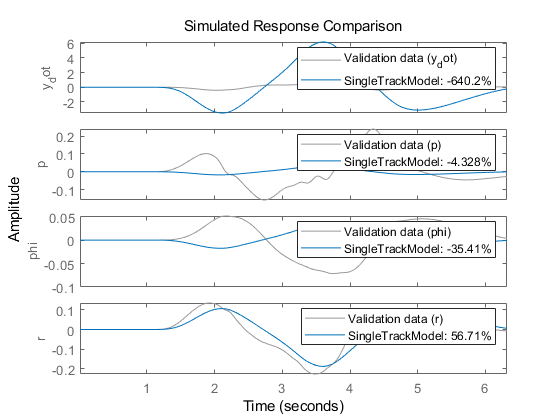


compare(data{1}, nlgr);

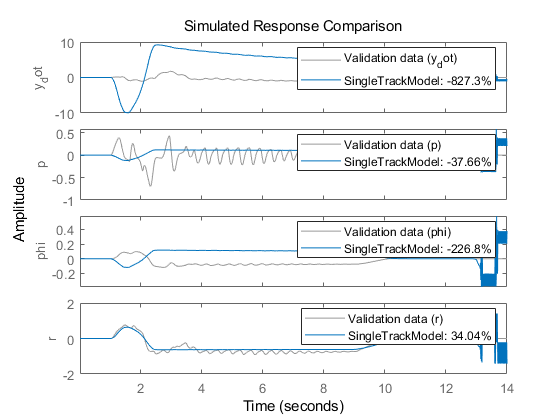

compare(data{2}, nlgr);

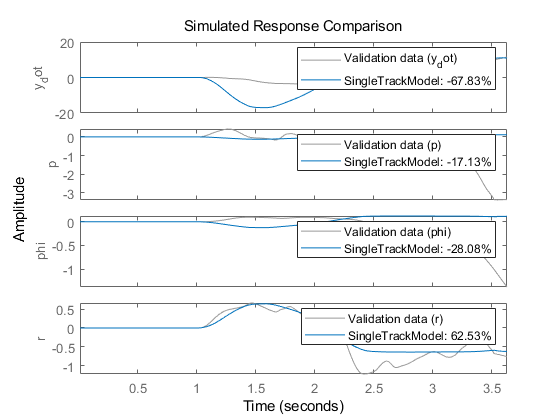

compare(data{3}, nlgr);


% nlgr = setinit(nlgr, 'Fixed', {false false}); % Estimate the initial states.
opt = nlgreyestOptions('Display', 'on');

opt.SearchOptions.MaxIterations = 50;

% opt.GradientOptions.Type = 'Refined';

opt.OutputWeight = [0 0 0 0;
                    0 0 0 0;
                    0 0 1 0;
                    0 0 0 0];

nlgr = nlgreyest(dataMerge, nlgr, opt);

fprintf('Trained model:')

Trained model:

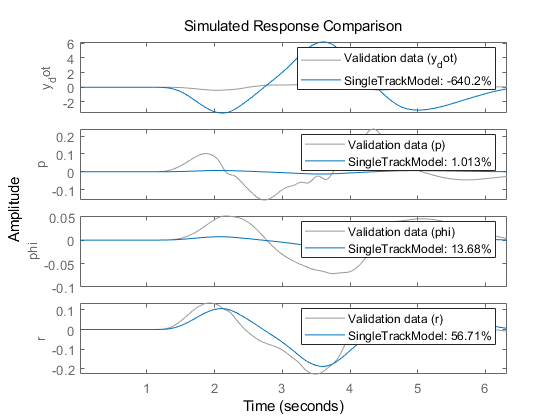

compare(data{1}, nlgr);

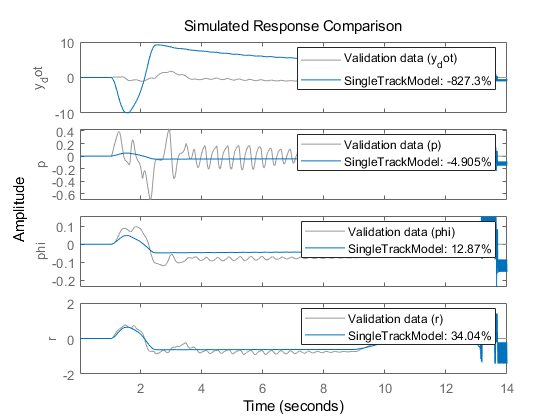

compare(data{2}, nlgr);

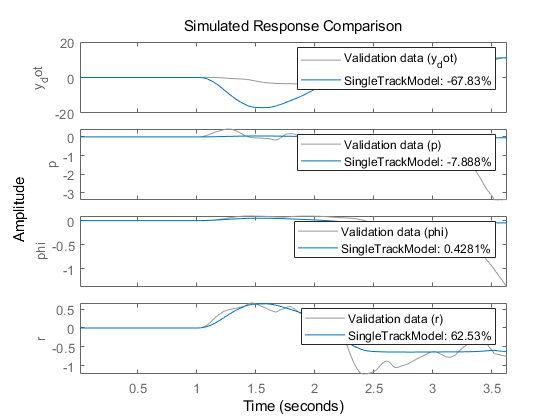

compare(data{3}, nlgr);

params_est = nlgr.Parameters;

Detection

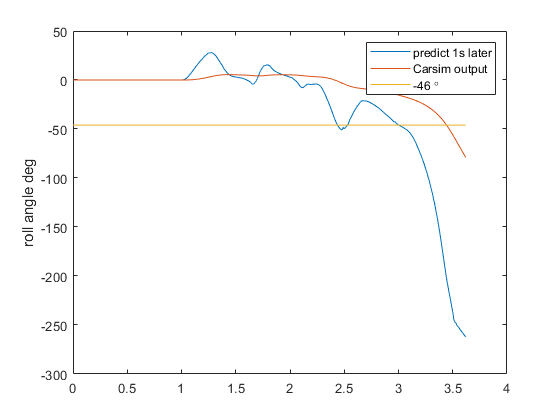

y_1s = zeros([length(data{3}.y),1]);
for i = 1:length(data{3}.y)
    [t,y] = ode45(@(t,y) ODEyawRoll2(t, y, data{3}.u(i,:),...
        params_est(1).Value, params_est(2).Value, params_est(3).Value,...
        params_est(4).Value, params_est(5).Value, params_est(6).Value,...
        params_est(7).Value, params_est(8).Value, params_est(9).Value,...
        params_est(10).Value, params_est(11).Value), [0 1], data{3}.y(i,:));
    
    y_1s(i) = y(end,3);
end

figure
plot(Time, rad2deg(y_1s))
hold on
plot(Time, rad2deg(data{3}.y(:,3)))
plot(Time, ones([length(data{3}.y),1])*-46)
legend('predict 1s later', 'Carsim output', '-46 \circ')
ylabel('roll angle deg')